# Parking car simulation

clear all;
clc;

addpath(genpath("./utils/"), genpath("./global_planner/"));
load("grid_map_parking.mat");
% map setting
map_size = size(grid_map);
G = 1; 

parkingSpaces = [10,29 ; 6,21 ; 11,17 ; 6,7 ; 14,29 ; 17,4; 11,11 ; 17,18 ; 4,27];

% Get the total number of rows in parkingSpaces
numRows = size(parkingSpaces, 1);

% random number between 1 and the total of parkingSpaces
randomIndex = randi(numRows);
randomIndex2 = randi(numRows);

while randomIndex == randomIndex2
    randomIndex2 = randi(numRows);
end

start = [3, 2];
goal = parkingSpaces(randomIndex, :);
goal2 = parkingSpaces(randomIndex2, :);

planner_name = "a_star";
planner = str2func(planner_name);


## Plan first route

tic
[path, flag, cost, expand] = planner(grid_map, start, goal);
time1 = toc

time1 = 0.0581

disp(path)

    17     4
    16     3
    15     3
    14     3
    13     3
    12     3
    11     3
    10     3
     9     3
     8     4
     8     5
     8     6
     8     7
     8     8
     8     9
     8    10
     8    11
     8    12
     8    13
     7    14
     6    15
     5    15
     4    15
     3    14
     3    13
     3    12
     3    11
     3    10
     3     9
     3     8
     3     7
     3     6
     3     5
     3     4
     3     3
     3     2



## Plan second route

newstart = [path(end - 14, 1), path(end - 14, 2)];
tic
[path2, flag2, cost2, expand2] = planner(grid_map, newstart, goal2);
time2 = toc

time2 = 0.0105

## Visualize route

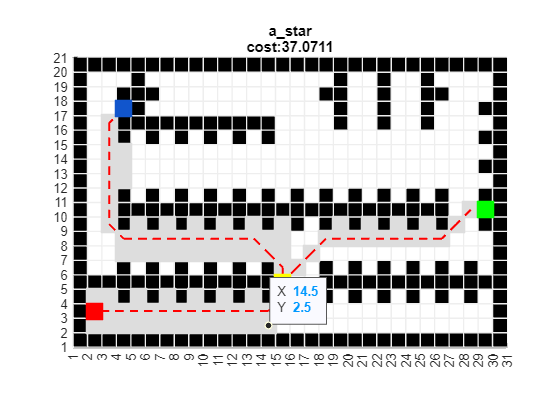

clf; hold on
% plot grid map
plot_grid(grid_map);

% plot expand zone
plot_expand(expand, map_size, G, planner_name);
plot_expand(expand2, map_size, G, planner_name);
% plot path
plot_path(path, G);
plot_path(path2, G)
% plot start and goal
plot_square(start, map_size, G, "#f00");
plot_square(goal, map_size, G, "#15c");
plot_square(goal2, map_size, G, "green");
plot_square(newstart, map_size, G, "yellow");

% title
title([planner_name, "cost:" + num2str(cost)], 'Interpreter','none');

hold off

ax = gca;
chart = ax.Children(91);
datatip(chart,19,1);